# **Redes Neuronais**

Trabalho prático CR - 2021/2022

clear all
close all

### Topologia da rede neuronal

topologia = "Pattern";
switch(topologia)
    case "Feedforward"
        net = feedforwardnet;
    case "Pattern"
        net = patternnet;
    case "Fitting"
        net = fitnet;
end

### Input da rede neuronal

folder = "imagens/start/*/*.png";
[input, tamanho] = process_images(folder);
target = gen_target(tamanho);

### Configurações da rede neuronal

% Função de Ativação
act_func = "logsig";

% Função de Treino
trn_func = "trainlm";

% Função de Divisão
dvd_func = "";

% Épocas (iterações)
epochs = 1000;

net.layers{1}.transferFcn = act_func;
net.trainFcn = trn_func;
net.divideFcn = dvd_func;
net.trainParam.epochs = epochs;

### Treino da rede neuronal

net = train(net, input, target);

### Simulação e desempenho da rede neuronal

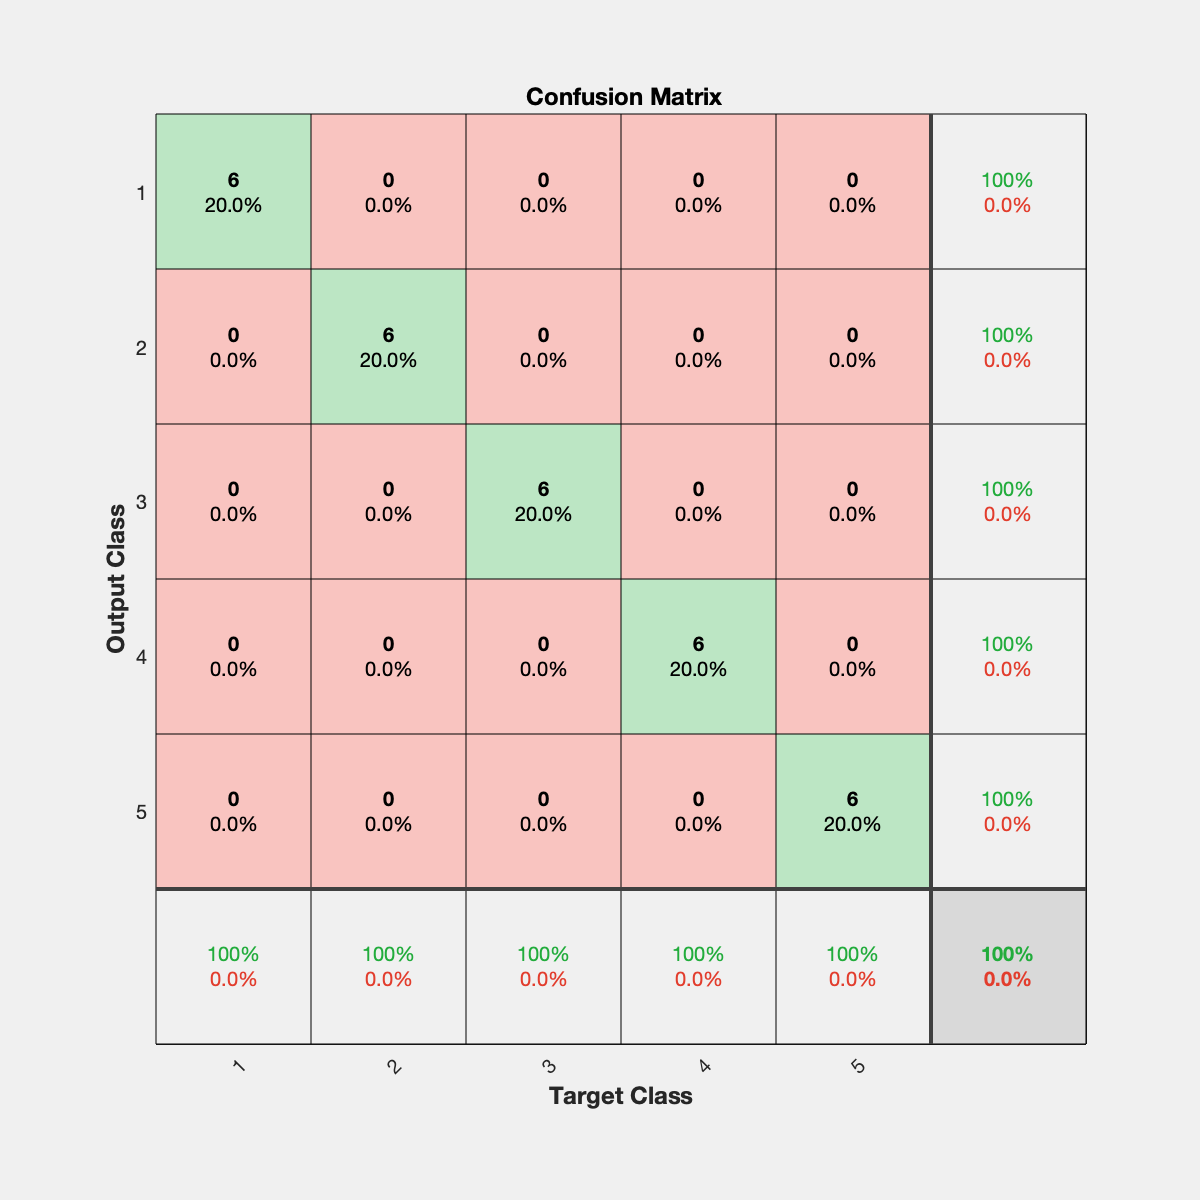

Precisão do teste (1): 100.000


Precisão do teste (2): 100.000


Precisão do teste (3): 100.000


Precisão do teste (4): 100.000


Precisão do teste (5): 100.000


nSim = 5;
accuracyFinal = 0;

for i=1 : nSim
    out = sim(net, input);
    plotconfusion(target, out);
    r = 0;
    for j=1 : size(out, 2)
        [a, b] = max(out(:,i));
        [c, d] = max(target(:,i));
        if(b == d) 
            r = r + 1;
        end
    end
    accuracy = r/size(out,2)*100;
    fprintf('Precisão do teste (%d): %.3f\n', i, accuracy);
    accuracyFinal = accuracyFinal + accuracy;
end


fprintf('Precisão total após %d testes: %.3f\n', nSim, accuracyFinal/nSim);

Precisão total após 5 testes: 100.000
